## Idealized MDOF

**Notes**:

- not defined c  properly

prompt = {'Enter no of DOF:','Enter time step:', 'Damping ratio, %'};
dlgtitle = 'MDOF Solver ';
dims = [1 100];
definput = {'3','0.02','5'};
input = inputdlg(prompt,dlgtitle,dims,definput);
ndof=str2num(cell2mat(input(1,1)));
dt=str2num(cell2mat(input(2,1)));
c=str2num(cell2mat(input(3,1)))/100;

if rem(ndof,1)~=0
validate = msgbox('Invalid Value for no of DOF', 'Error','error');
end

massip=inputdlg('Enter all discrete masses (separated by space):','Masses corresponding to DOF', [1 50]);
mass=str2num(cell2mat(massip));
if size(mass)~=ndof
    msgbox('No of masses does not match no of DOFs','Error in input!','error')
    return;
end
kip=inputdlg('Enter all discrete stiffness (separated by space):','Stiffness corresponding to DOF', [1 50]);
kval=str2num(cell2mat(kip));
if size(mass)~=ndof
    msgbox('No of stiffness does not match no of DOFs','Error in input!','error')
    return;
end

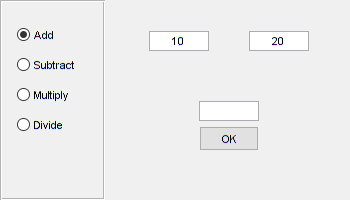

 hFig = figure('Visible','off', 'Menu','none', 'Name','Calculator', 'Resize','off', 'Position',[100 100 350 200]);
    movegui(hFig,'center')          %# Move the GUI to the center of the screen

    hBtnGrp = uibuttongroup('Position',[0 0 0.3 1], 'Units','Normalized');
    uicontrol('Style','Radio', 'Parent',hBtnGrp, 'HandleVisibility','off', 'Position',[15 150 70 30], 'String','Add', 'Tag','+')
    uicontrol('Style','Radio', 'Parent',hBtnGrp, 'HandleVisibility','off', 'Position',[15 120 70 30], 'String','Subtract', 'Tag','-')
    uicontrol('Style','Radio', 'Parent',hBtnGrp, 'HandleVisibility','off', 'Position',[15  90 70 30], 'String','Multiply', 'Tag','*')
    uicontrol('Style','Radio', 'Parent',hBtnGrp, 'HandleVisibility','off', 'Position',[15  60 70 30], 'String','Divide', 'Tag','/')

    uicontrol('Style','pushbutton', 'String','OK', 'Position',[200 50 60 25], 'Callback',{@button_callback})

    hEdit1 = uicontrol('Style','edit', 'Position',[150 150 60 20], 'String','10');
    hEdit2 = uicontrol('Style','edit', 'Position',[250 150 60 20], 'String','20');
    hEdit3 = uicontrol('Style','edit', 'Position',[200  80 60 20], 'String','');

    set(hFig, 'Visible','on')        %# Make the GUI visible

switch 1
    case 1
       g=386;
    case 2
        g=9.81;
end

% if size(gm,2)==1
%     
% end


answer = questdlg('How would you like to solve?','Customization','Default','Advanced','Cancel','sa');


switch answer
    case 'Default'

    case 'Advanced'
        fig = uifigure('Name','Choose ground motion type','Position',[680 678 398 271]);
        bg = uibuttongroup(fig,'Position',[137 113 123 85]); 
        rb1 = uiradiobutton(bg,'Position',[10 60 91 15],'Text','agceleration','Value',true);
        rb2 = uiradiobutton(bg,'Position',[10 38 91 15],'Text','Velocity');
        rb3 = uiradiobutton(bg,'Position',[10 16 91 15],'Text','Displcement');
        pause(2);
        if rb2.Value==1
            msgbox('ok')
        else
            msgbox('erroe')
        end
% switch cs
%     case 
%         gamma=0.5; beta=0.25; 
% end
%         end        
%     case 'Cancel'
%         return
end
% Rayleigh Damping

[file,path,indx] = uigetfile( {'*.txt;*.mat;*.AT2;*.VT2;*.DT2','Ground Motion Files (*.txt,*.mat,*.AT2,*.VT2,*.DT2)';'*.*', 'All Files (*.*)'},'Select a Ground Motion File','MultiSelect', 'on');
gm=fullfile(path,file);
data=importdata(gm); 

Error using importdata (line 137)
Unable to open file.

agi=data(:,2);
tg=data(:,1);
n=size(agi,1);
figure; plot(tg,agi);  title('Input Ground Motion')
xlabel('Time, s');
ylabel('agceleration');
grid on
xlim([0 tg(n)])

function run()
m=zeros(ndof);
k=zeros(ndof);
for i=1:ndof
    m(i,i)=mass(i);
    if i<ndof
        k(i,i)=kval(i)+kval(i+1);
    else
        k(i,i)=kval(i);
    end
    if i>1
        k(i,i-1)=-kval(i);
        k(i-1,i)=-kval(i);
    end
end

a1=0.00275; 
C=a1*k;
r=[1 1 1]'; 

dtrecord=tg(2)-tg(1);
t=(0:dt:(n-1)*dtrecord)';
%linear interpolation for intermediate point
ag=interp1(tg,agi,t);

u(:,1)=[0; 0; 0]; 
v(:,1)=[0; 0; 0]; 
a(:,1)=m^(-1)*(-m*r*ag(1)*g-C*v(:,1)-k*u(:,1)); 
gamma=0.5; beta=0.25; 
Knn=1/(beta*dt^2)*m+gamma/(beta*dt)*C+k;
for i=1:n-1     
    x=(1/(beta*dt^2)*m+gamma/(beta*dt)*C)*u(:,i);     
    y=(1/(beta*dt)*m+(gamma/beta-1)*C)*v(:,i);     
    z=((1/(2*beta)-1)*m+dt*(gamma/(2*beta)-1)*C)*a(:,i);     
    Ft=-m*r*ag(i+1)*g+x+y+z;     
    u(:,i+1)=Knn^(-1)*Ft;    
    a(:,i+1)=1/(beta*dt^2)*(u(:,i+1)-u(:,i)-dt*v(:,i)-(0.5-beta)*dt^2*a(:,i));     
    v(:,i+1)=v(:,i)+dt*(1-gamma)*a(:,i)+dt*gamma*a(:,i+1);     
end 

for i=1:ndof
    figure;plot(t,u(i,:)); grid on; title(['Story ', num2str(i), ' Lateral Displagement Time History']); 
    xlabel('Time, s'); ylabel('Displagement, in'); xlim([0 t(n)])
end
    
%Maximum responses 
for i=1:ndof
    if i==1
        sdmax(i)=max(abs(u(i,:)));
    else
        sdmax(i)=max(abs(u(i,:)-u(i-1,:))); 
    end
    sf(i)=kval(i)*sdmax(i);
    dmax(i)=max(abs(u(i,:)));
end


fprintf('Maximum stroy drift  corresponding to each story repectively \n');disp(sdmax);
fprintf('Maximum base shear corresponding to each story repectively \n');disp(sf);
fprintf('Maximum displacement corresponding to each story repectively \n');disp(dmax);
end

% myicon = imread('ssmiley.png'); 
% msgbox('Operation Completed','Success','custom',myicon);

%# callback function
    function button_callback(src,ev)
        v1 = str2double(get(hEdit1, 'String'));
        v2 = str2double(get(hEdit2, 'String'));
        switch get(get(hBtnGrp,'SelectedObject'),'Tag')
            case '+',  res = v1 + v2;
            case '-',  res = v1 - v2;
            case '*',  res = v1 * v2;
            case '/',  res = v1 / v2;
            otherwise, res = '';
        end
        set(hEdit3, 'String',res)
    end